## Problem set 2  - Metodi Matematici per la Finanza, AA 2023-24.

Postiglioni Francesco n. 788731

Formisano Andrea n. 787681

clear
close all
clc

## European call option and Asian call option pricing using the Montecarlo method

In this code, by taking advantage of MatLab's computational power, we're going to use the Montecarlo method (and the Kolmogorov Strong Law of Large Numbers)

in order to price one European call option and one Asian call option by simulating 1000 processes each. In order to generate 1000 random processes the built in pseudorandomical MatLab generation function (uniform [0, 1]) is going to be used and then inverted. Finally, given the simulations, the standart payoff function relative

to each type of option will by used, thus exstimating (with a little level of uncertainty) the actualized price. 

## Data initialization

For both of the option contract's it's assumed that the initial stock price (underlying price) is $S_0 = \$100
$, their volatility is $\sigma = 20 \%$ and market risk free rate is 

taken as the current ESTER ECB rate on [https://www.ecb.europa.eu/stats/financial_markets_and_interest_rates/euro_short-term_rate;](https://www.ecb.europa.eu/stats/financial_markets_and_interest_rates/euro_short-term_rate;) for the purpose of this 

code the reference date is 22/11/2023 (last update of the ESTER rate). The "risk-free" rate so taken will amount to$\\euroSTR = 3.901\%$. 

S0 = 100;
volatility = 0.2;
r = 0.03901;

Number of simulations/scenarios.

n = 1000;

## European call option pricing

Even though Black&Scholes method provides us with a closed formula for the option price, we're gonna be using the Kolmogorov strong law of large numbers to render it as

an approximation found as the average of $n = 1000$ random payoffs calculated like this: 

$P = max(S_t-K,0)$     where $S_t$ is defined as $S_t = S_0\times e^{((r-\frac{\sigma^2}{2})\times T+\sigma \times \sqrt{T} \times Z)$

Z, assuming the stock distributes as a lognormal, is the inverted normal distribution; basically the stochastic part of the equation replicated a great number of times (indipendently) in Montecarlo simulations. 

Let's proceed by establishing for the problem an ATM strike price of $K = \$100$ and a time span of $T = 3 \space months$.

K = 100;

Time in years(for a short term risk free rate).

T = 0.25;

Now the most important part: creating for $n = 1000$ times a random normal univariate function useful in simulating the same number of $S_T$ prices to be used as an input in the 

approx. payoff function. 

Let's start by allocating memory for the variables.

Z = NaN(n,1);
St = NaN(n,1);
payoff = NaN(n,1);

Let's now cycle through every simulation. 

for i = 1:n
    Z(i) = randn(1);
    St(i) = S0*exp((r-(volatility^2)/2)*T+volatility*sqrt(T)*Z(i));
    payoff(i) = max(St(i)-S0,0);
end

Representing the $S_T$  array in an histogram to highlight its normal distribution. 

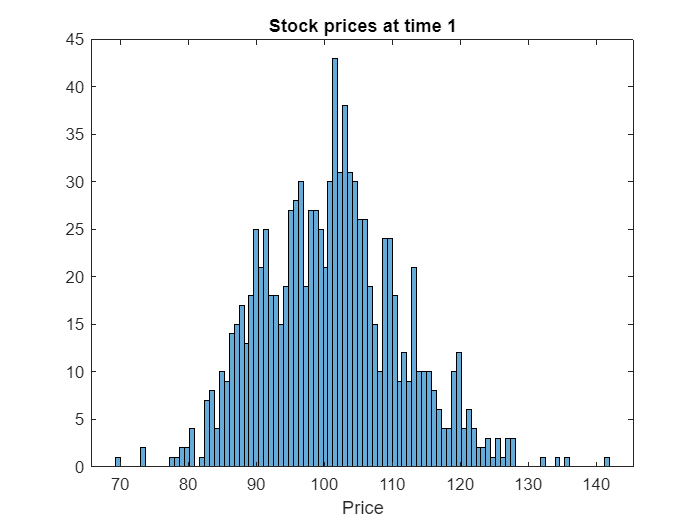

figure;
histogram(St,100);
grid off;
title('Stock prices at time 1');
xlabel('Price');

Now, after we have simulated 1000 paths and payoffs, we can render the approximate European call option price as the actualized mean of the 1000 payoffs:


$$C_0^{approx}= e^{-rT}\times\space\frac{P_1+...+P_n}{n}$$


Once found this approx. value we can compare it with the real expected value of the option payoff (remember that for the plain vanilla European call option Black&Scholes provide a closed formula.

$C_0^*=E[e^{-rT}\times S_0 \times e^{((r-\frac{\sigma^2}{T})\times T+\sigma \times \sqrt{T} \times Z)}]$ where the closed formula is $
	\mathrm C(\mathrm S,\mathrm t)= \mathrm N(\mathrm d_1)\mathrm S - \mathrm N(\mathrm d_2) \mathrm K \mathrm e^{-rt}

$ with $\mathrm d_1= \frac{1}{\sigma \sqrt{\mathrm t}} \left[\ln{\left(\frac{S}{K}\right)} + t\left(r + \frac{\sigma^2}{2} \right) \right]$, $\mathrm d_2= \frac{1}{\sigma \sqrt{\mathrm t}} \left[\ln{\left(\frac{S}{K}\right)} + t\left(r - \frac{\sigma^2}{2} \right) \right]$

C_approx = exp(-1*r*T)*mean(payoff);
C_correct = blsprice(S0,K,r,T,volatility);

In an explicit form also. 

d1 = ((log(S0/K)+T*(r+volatility^2/2))/(volatility*sqrt(T)));
d2 = ((log(S0/K)+T*(r-volatility^2/2))/(volatility*sqrt(T))); 
explCallPrice = normcdf(d1)*S0-normcdf(d2)*K*exp(-1*r*T);

Calculating the percentage error for this process.

Error = abs(C_approx-C_correct)/(C_correct)*100;
names = {'Approx. price', 'Correct price', 'Percentage error'};
EuropeanCallOption = table(C_approx, C_correct, Error,'VariableNames',names);
disp(EuropeanCallOption);

    Approx. price    Correct price    Percentage error
    _____________    _____________    ________________

       4.5074           4.4725            0.77992     



Showing the convergence of the method through the Kolmogorov strong law of large numbers.

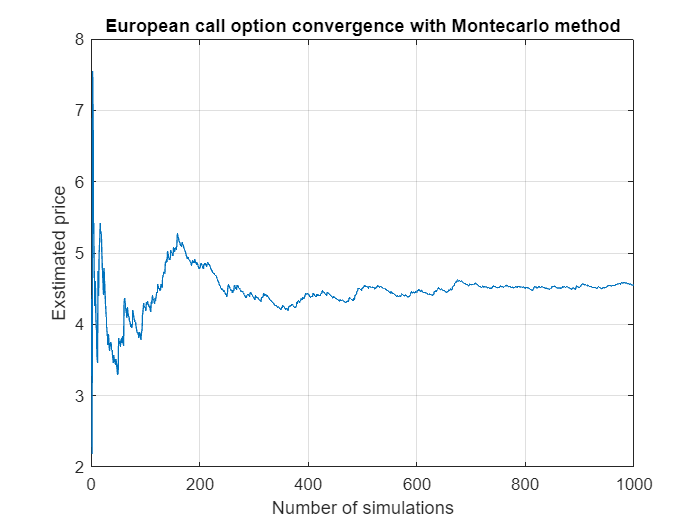

figure;
plot(cumsum(payoff) ./ (1:n)');
title('European call option convergence with Montecarlo method');
xlabel('Number of simulations');
ylabel('Exstimated price');
grid on;

## Asian call option pricing

We can now repeat the same process for the Asian option, also referred to as "average value option", where the payoff is determined as a mean between the undelying asset price between two instants in time usually assigned as the initial spot price and the expiration date undelying price.


$$P = max(\frac{S_{T2}+S_{T1}}{2}-K,0)$$


Since is needed - for the general case when $T1\not =T0$ - a new simulated price for the first period, we'll resort to using not a normal univariate distribution but a bivariate standard normal function for $Z$ and $W$.

For this specific problem all the data remains the same but $T_1= 1 \space month$ and $T_2 = 3\space months$ so that we can simulate the prices for two time instants like that:

$S_{T_1} = S_0\times e^{((r-\frac{\sigma^2}{2})\times T_1+\sigma \times \sqrt{T_1} \times Z)$ and $S_{T_2} = S_{T_1}\times e^{((r-\frac{\sigma^2}{2})\times (T_2 -T_1)+\sigma \times \sqrt{T_2-T_1} \times W)$

As done before we start with variable inizialization and memory allocation.

T1 = 1/12;
T2 = T;
nperiod = 2;
mu = zeros(1, nperiod);
sigma = eye(nperiod, nperiod);
multivariate = NaN(n,2);
St1 = NaN(n,1); St2 = NaN(n,1);
asianpayoff = NaN(n,1);

We can now start the montecarlo simulation.

for i = 1:n
    multivariate(i, :) = mvnrnd(mu, sigma);
    St1(i) = S0*exp((r-(volatility^2)/2)*T1+volatility*sqrt(T1)*multivariate(i, 1));
    St2(i) = St1(i)*exp((r-(volatility^2)/2)*(T2-T1)+volatility*sqrt(T2-T1)*multivariate(i, 2));
    asianpayoff(i) = max((St2(i)+St1(i))/2-K,0);
end

Representing the $S_{T_1}\space and\space S_{T_2}$  arrays in an histogram to highlight their normal distribution. 

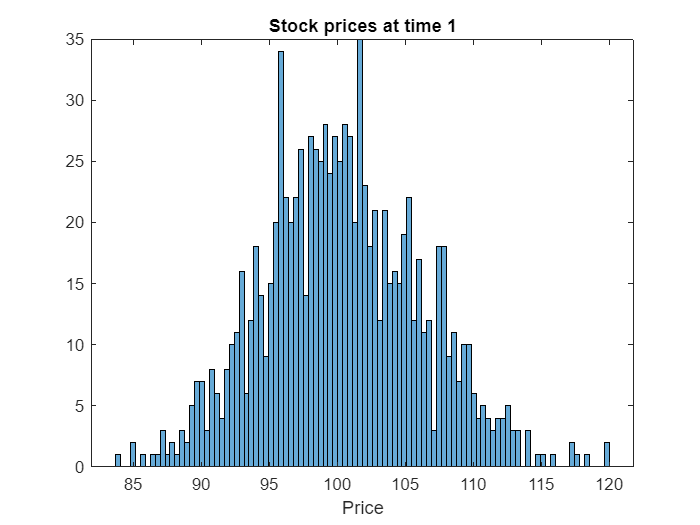

figure;
histogram(St1,100);
grid off;
title('Stock prices at time 1');
xlabel('Price');

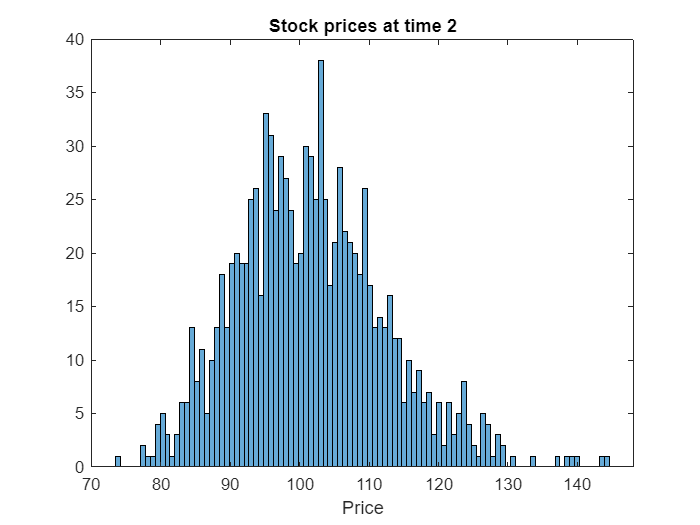

figure;
histogram(St2,100);
grid off;
title('Stock prices at time 2');
xlabel('Price');

Given the Asian option payoff array we are now capable of approximating the expected value of its price as the actualized mean of all the payoffs found as per the Kolmogorov strong law of large numbers. 

$AC_0^*=E[e^{-rT_2}\times max(\frac{S_{T2}-S_{T1}}{2},0)]
$ approx. by $AC_0^{approx}= e^{-rT_2}\times\space\frac{P_1+...+P_n}{n}$

ac_approx = exp(-1*r*T2)*mean(asianpayoff);

Showing the convergence of the method through the Kolmogorov strong law of large numbers.

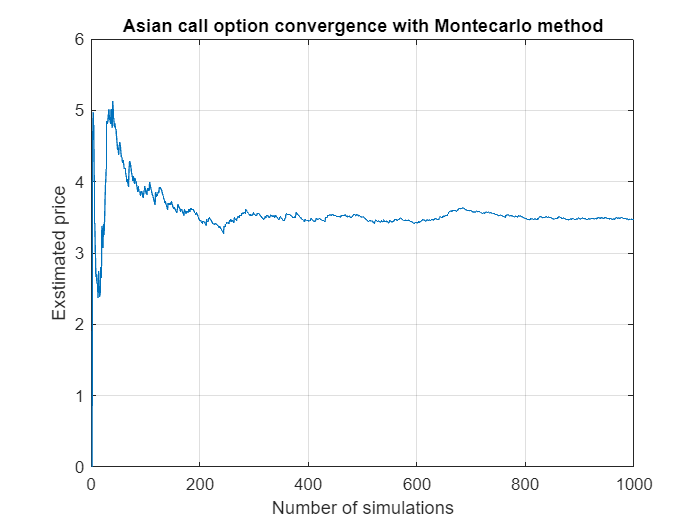

figure;
plot(cumsum(asianpayoff) ./ (1:n)');
title('Asian call option convergence with Montecarlo method');
xlabel('Number of simulations');
ylabel('Exstimated price');
grid on;

name = {'Approx. European call','Approx. Asian call','Difference'};
asiancalloption = table(C_approx, ac_approx,C_approx - ac_approx, 'VariableNames',name);
disp(asiancalloption);

    Approx. European call    Approx. Asian call    Difference
    _____________________    __________________    __________

           4.5074                  3.4352            1.0721  



## Final considerations

As we can see by the results obtained in the previous lines of code we can conclude that the asian call option will always have a significantly lower price than the standard (plain vanilla) European call option. As a matter of fact if we consider an option's price an expression of is intrinsic value and of its time value, it is easy to think the latter as directly proportional to its maturity and its undelying asset's volaitlity; thus the volatiltiy of the underlying asset would be significantly higher than the volaitlity of its mean (given two periods) making our conclusion rational. 